clear all; clc; close all;

# Model-Based and Data-Driven Co-Design of Robust DC Microgrids using Dissipativity

## 1. Generating a Random DC Microgrid

rng(7);
saveImages = 0;
linkFiltThresh = 1e-4;
N = 4;    % number of DGs  

% Generate a DC Microgrid
net = getARandomDCMicrogrid(N);

Steady-state design SUCCESS!
SS current usage (fraction) at each DG: 5.406694e-01 
SS voltage levels (Volt) at DGs: 


ans =     0.9367    0.9620    0.9569    0.9617


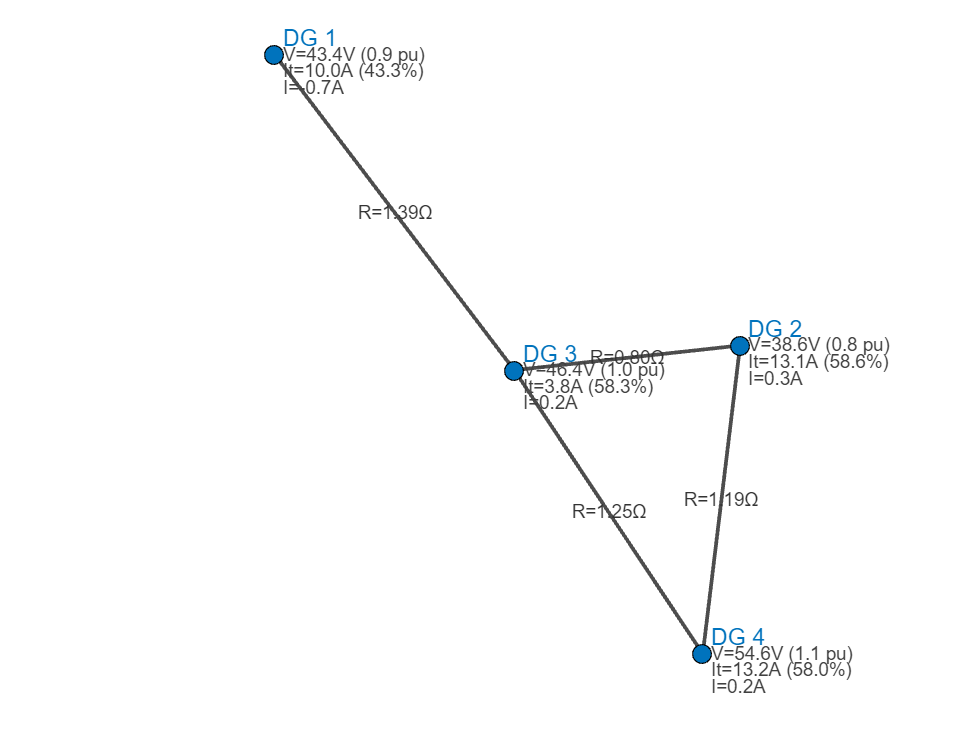


% Draw topology and initial condition
fig = figure('Color','w','Name','DC Microgrid Example');
figure(fig); clf; 
ax = axes(fig); net.draw(ax);


% Save Figure
if saveImages
    adjustAxesPadding(ax, 0, 0, 0, 0);
    saveFigureHighRes('DCMG', ...
        'Width', 6, 'Height', 6, 'Units', 'inches', ...
        'DPI', 600, 'FontSize', 6);
end

% Simulation data
dt_system = 1e-5;
tspan = 0:dt_system:0.2;          % seconds
dt_noise = 1e-5;
sigma_noise = 0.00001*diag([0.1; 0.1]);      % Noise variance in I_i and V_{ti} channels
net.setupNoise(tspan, dt_noise, sigma_noise);   % dt_noise, sigma

% Save the network
save("netFile","net","saveImages","linkFiltThresh","tspan","N");

## 2. Model-Based Global Stabilizing Controller

clear all; clc; close all;
rng(7);
load netFile.mat;
figTitle = 'MB-GSC'

figTitle = 'MB-GSC'

useData = 0;

% Model-based design of a global stabilizing controller 
[AdjMat, KMat, out] = net.design_MB_GSC(linkFiltThresh,useData);

Model-based GSC design SUCCESS!


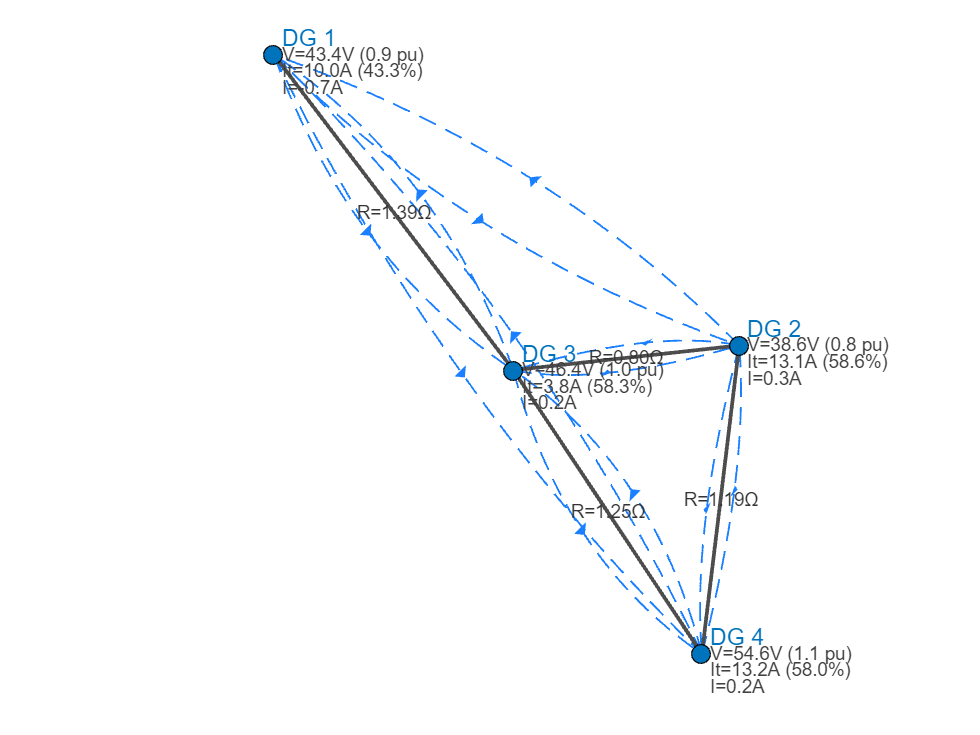


% Draw topology 
fig = figure('Color','w','Name',[figTitle,'-Topology']);
figure(fig); clf; 
ax = axes(fig); 
net.draw(ax);


% Save Figure
if saveImages
    adjustAxesPadding(ax, 0, 0, 0, 0);
    saveFigureHighRes([figTitle,'-Topology'], ...
        'Width', 6, 'Height', 6, 'Units', 'inches', ...
        'DPI', 600, 'FontSize', 6);
end

% Simulating
x0 = net.getStateVector();
[t, X, U, Xs, Us] = net.simulate(tspan, x0, useData);

Starting Stage 1...
Finished Stage 1, getting ready for Stage 2...
Starting Stage 2...
Finished Stage 2, getting ready for Stage 3...
Starting Stage 3...
Finished Stage 3, getting ready for Stage 4...
Starting Stage 4...
Finished Stage 4, getting ready for Stage 5...
Steady-state design SUCCESS!
SS current usage (fraction) at each DG: 6.107315e-01 
SS voltage levels (Volt) at DGs: 


ans =     0.9366    0.9380    0.9555    0.9607


Starting Stage 5...
Finished Stage 5, getting ready for Stage 6...
Starting Stage 6...
Finished Stage 6, getting ready for Stage 7.
Starting Stage 7...
Finished Stage 7, i.e., the Final.


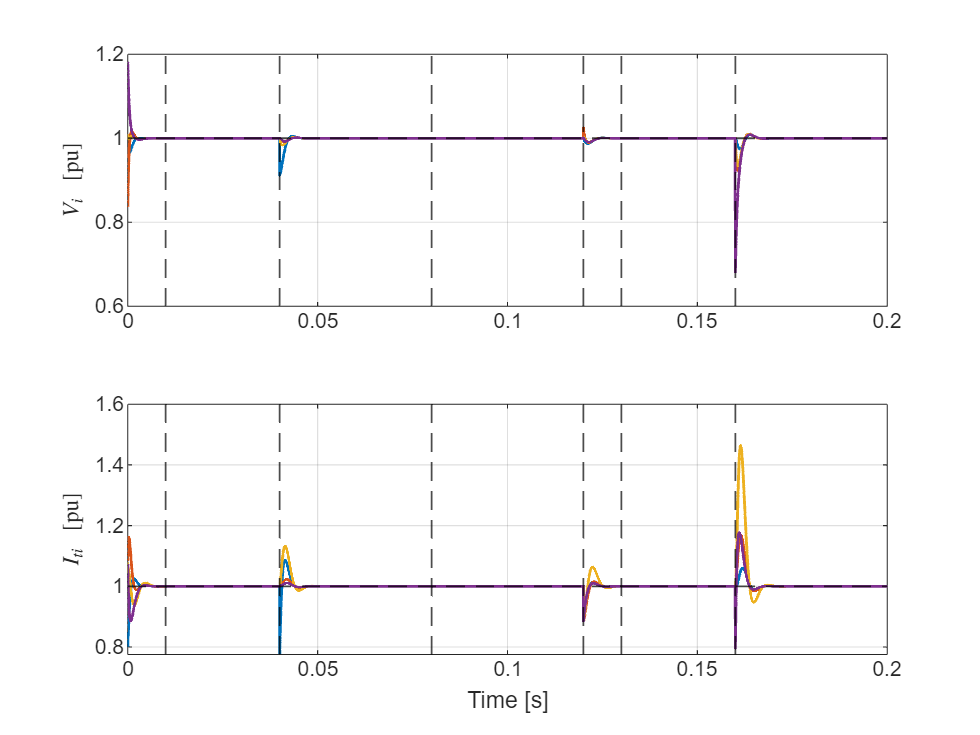

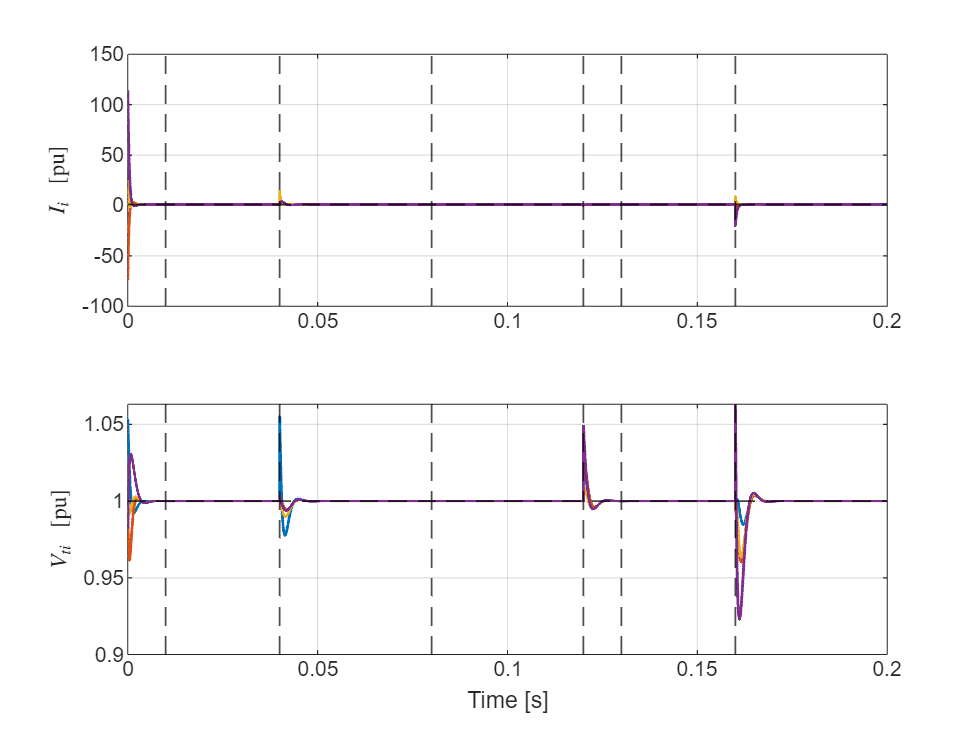

trajDataPU = drawStateTrajectories(t,X,U,Xs,Us,N,saveImages,figTitle);


% xf = X(end,:)'
% uf = U(end,:)'
% res1 = net.A*xf + net.BBar*uf + net.E*net.wBar
% fprintf('||steady-state residual||_2 = %.3e\n', norm(res1));
% xs = Xs(end,:)'
% us = Us(end,:)'
% % xs = net.x_s
% % us = [net.D, net.DBar]*[net.ss.I_ss; net.u_s]
% res2 = net.A*xs + net.BBar*us + net.E*net.wBar
% fprintf('||steady-state residual2||_2 = %.3e\n', norm(res2));


## 3. Model-Based Co-Designed Distributed Robust Controller

clear all; clc; close all;
rng(7);
load netFile.mat;
useData = 0;
figTitle = 'MB-DRC';

% Model-based co-design of a distributed robust controller
[AdjMat, KMat, out] = net.codesign_MB_DRC(linkFiltThresh);

Local Design Success! (nu,rho)=(-0.13542,0.014772)K=[0.02359,-4.7983]
Local Design Success! (nu,rho)=(-0.16191,0.012356)K=[-0.094452,-5.0135]
Local Design Success! (nu,rho)=(-0.30639,0.0065288)K=[-0.081362,-5.1449]
Local Design Success! (nu,rho)=(-0.1546,0.01294)K=[0.020177,-5.3717]
Model-based DRC co-design SUCCESS!


kVal = 1

detVal = 2.8767e-04

kVal = 2

detVal = 8.2755e-08

kVal = 3

detVal = 2.6624e-11

kVal = 4

detVal = 8.5657e-15

kVal = 5

detVal = 5.4689e-18

kVal = 6

detVal = 3.4917e-21

kVal = 7

detVal = 1.2709e-24

kVal = 8

detVal = 4.6258e-28

kVal = 9

detVal = 4.6258e-28

kVal = 10

detVal = 4.6258e-28

kVal = 11

detVal = 4.6258e-28

kVal = 12

detVal = 4.6258e-28

kVal = 13

detVal = 4.6258e-28

kVal = 14

detVal = 4.6258e-28

kVal = 15

detVal = 4.6258e-28

kVal = 16

detVal = 4.6258e-28

kVal = 17

detVal = -2.3788e-25

kVal = 18

detVal = 4.3005e-21

kVal = 19

detVal = -9.5977e-18

kVal = 20

detVal = 1.0893e-13

kVal = 21

detVal = -9.6786e-11

kVal = 22

detVal = 1.5372e-07

kVal = 23

detVal = -6.1196e-07

kVal = 24

detVal = 0.0067

kVal = 25

detVal = 78.7725

kVal = 26

detVal = 9.2297e+05

kVal = 27

detVal = 1.0814e+10

kVal = 28

detVal = 1.2671e+14

kVal = 29

detVal = 1.4847e+18

kVal = 30

detVal = 1.7396e+22

kVal = 31

detVal = 2.0382e+26

kVal = 32

detVal = 2.3882e+30

k_crit = 23

minor_crit = -6.1196e-07

minors = 1.0e+30 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


epsilon    = -6.1802e-01
||K||-weighted    = 1.6060e-05
gamma^2 (global)  = 1.1717e+04
trace(P)          = 8.5495e-03


phyErr = 1.4652e-10

||D'K - PȲD'|| = 1.4652e-10


KBarVal =     0.0037   -7.5637   -0.0021    0.0021   -0.0002    0.0002   -0.0014    0.0014
   -0.0015    0.0015    0.0061   -5.9422    0.0004   -0.0004   -0.0050    0.0050
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -1.6349   -0.0000    0.0000
   -0.0011    0.0011   -0.0058    0.0058   -0.0003    0.0003    0.0073   -5.8309


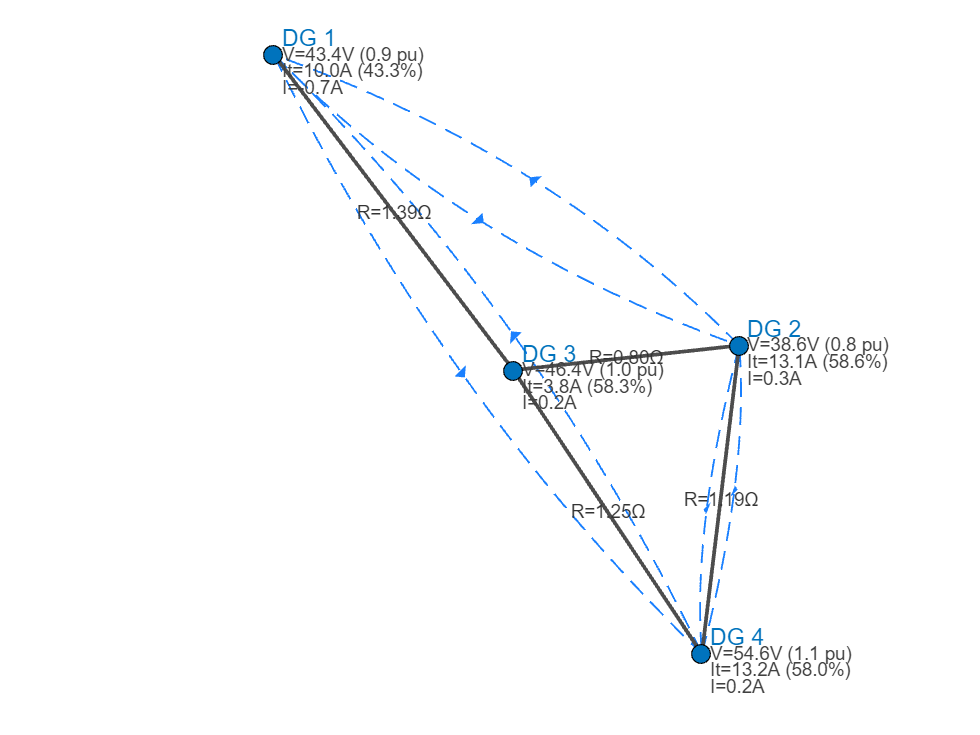


% Draw topology 
fig = figure('Color','w','Name',[figTitle,'-Topology']);
figure(fig); clf; 
ax = axes(fig); 
net.draw(ax);


% Save Figure
if saveImages
    adjustAxesPadding(ax, 0, 0, 0, 0);
    saveFigureHighRes([figTitle,'-Topology'], ...
            'Width', 6, 'Height', 6, 'Units', 'inches', ...
            'DPI', 600, 'FontSize', 6);
end

% Simulating
x0 = net.getStateVector();
useData = 0;
[t, X, U, Xs, Us] = net.simulate(tspan, x0, useData);

Starting Stage 1...
Finished Stage 1, getting ready for Stage 2...
Starting Stage 2...
Finished Stage 2, getting ready for Stage 3...
Starting Stage 3...
Finished Stage 3, getting ready for Stage 4...
Starting Stage 4...
Finished Stage 4, getting ready for Stage 5...
Steady-state design SUCCESS!
SS current usage (fraction) at each DG: 6.107315e-01 
SS voltage levels (Volt) at DGs: 


ans =     0.9366    0.9380    0.9555    0.9607


Starting Stage 5...
Finished Stage 5, getting ready for Stage 6...
Starting Stage 6...
Finished Stage 6, getting ready for Stage 7.
Starting Stage 7...
Finished Stage 7, i.e., the Final.


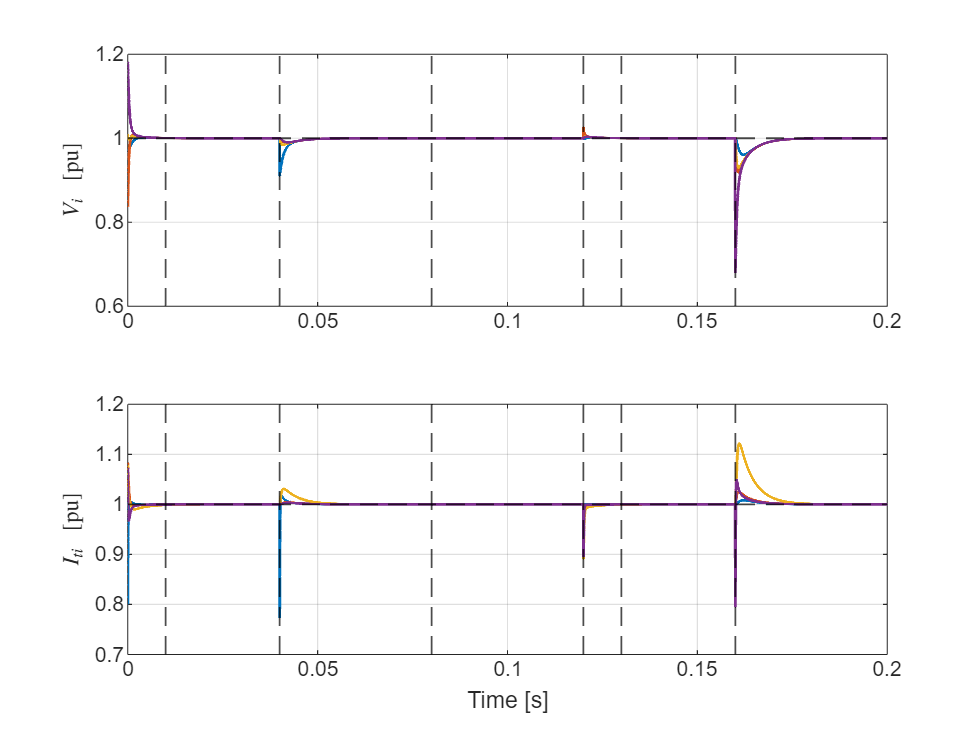

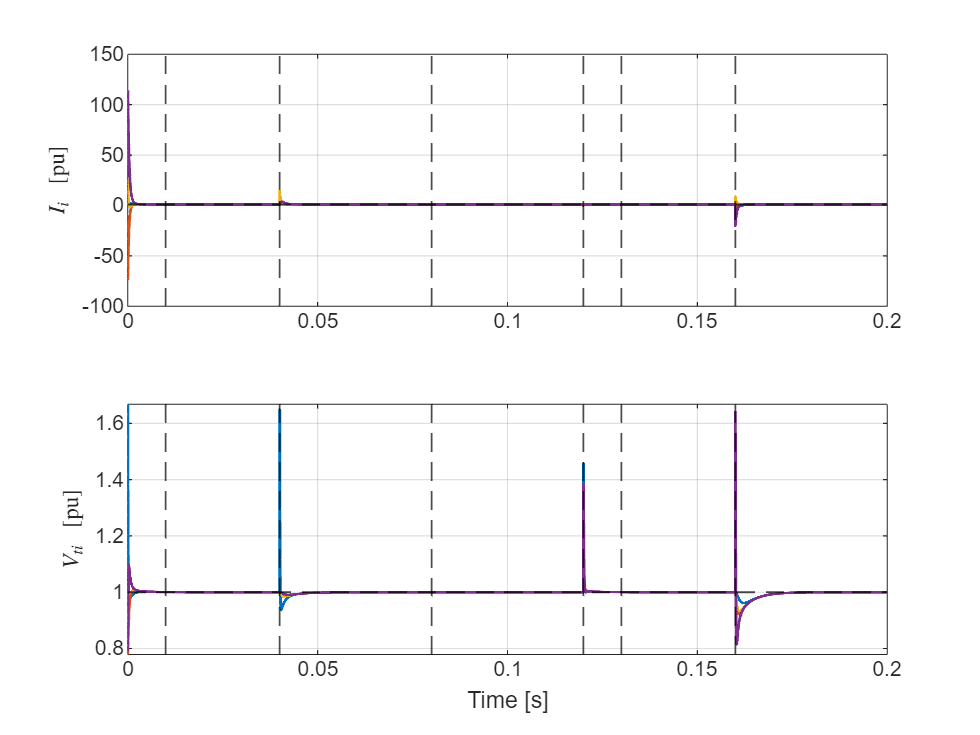

trajDataPU = drawStateTrajectories(t,X,U,Xs,Us,N,saveImages,figTitle);

## 4. Data-Driven Co-Designed Distributed Robust Controller

clear all; clc; close all;
rng(7);
load netFile.mat;
useData = 1;
figTitle = 'DD-DRC';


% Simulating
x0 = net.getStateVector();
[t, X, U, Xs, Us] = net.simulate(tspan, x0, useData, linkFiltThresh);

Model-based GSC design SUCCESS!
Starting Stage 1...
Finished Stage 1, getting ready for Stage 2...


meanAbsDist = 1.0e-07 *

    0.7995    0.7825


meanAbsDiscErr =     3.5793    0.2427


Local Design Success! (nu,rho)=(-3.6995,4.6113e-09)K=[-0.020425,-0.005716]
Local Design Success! (nu,rho)=(-4.1458,4.5637e-09)K=[0.033143,-0.038608]
Local Design Success! (nu,rho)=(-4.7232,2.5053e-09)K=[-0.0035208,0.0029845]
Local Design Success! (nu,rho)=(-2.8622,8.2623e-09)K=[0.014183,-0.010838]


scaleQ = 1.8262e+05

Data-driven DRC co-design SUCCESS!


kVal = 1

detVal = 881.5155

kVal = 2

detVal = 7.7707e+05

kVal = 3

detVal = 6.8500e+08

kVal = 4

detVal = 6.0384e+11

kVal = 5

detVal = 5.3229e+14

kVal = 6

detVal = 4.6922e+17

kVal = 7

detVal = 4.1363e+20

kVal = 8

detVal = 3.6462e+23

kVal = 9

detVal = 3.6462e+23

kVal = 10

detVal = 3.6462e+23

kVal = 11

detVal = 3.6462e+23

kVal = 12

detVal = 3.6462e+23

kVal = 13

detVal = 3.6462e+23

kVal = 14

detVal = 3.6462e+23

kVal = 15

detVal = 3.6462e+23

kVal = 16

detVal = 3.6462e+23

kVal = 17

detVal = -1.3026e+23

kVal = 18

detVal = -4.4647e+24

kVal = 19

detVal = 8.9876e+23

kVal = 20

detVal = 5.0291e+25

kVal = 21

detVal = -2.8569e+25

kVal = 22

detVal = -1.8130e+27

kVal = 23

detVal = 2.9128e+26

kVal = 24

detVal = 1.7583e+28

kVal = 25

detVal = 1.3293e+26

kVal = 26

detVal = -4.8963e+25

kVal = 27

detVal = -3.8201e+24

kVal = 28

detVal = 1.7218e+24

kVal = 29

detVal = 1.5055e+22

kVal = 30

detVal = -9.9863e+21

kVal = 31

detVal = -6.1034e+20

kVal = 32

detVal = 1.9151e+20

kVal = 33

detVal = 7.8852e+17

kVal = 34

detVal = 1.8503e+16

kVal = 35

detVal = 1.2873e+15

kVal = 36

detVal = 7.5761e+12

kVal = 37

detVal = 1.7907e+11

kVal = 38

detVal = 1.1416e+07

kVal = 39

detVal = 5.9072e+05

kVal = 40

detVal = 1.6028e+03

kVal = 41

detVal = -1.6031e+03

kVal = 42

detVal = 1.6031e+03

kVal = 43

detVal = -1.6036e+03

kVal = 44

detVal = 1.6036e+03

kVal = 45

detVal = -1.6052e+03

kVal = 46

detVal = 1.6052e+03

kVal = 47

detVal = -1.6056e+03

kVal = 48

detVal = 1.6056e+03

kVal = 49

detVal = 0

kVal = 50

detVal = 0

kVal = 51

detVal = 0

kVal = 52

detVal = 0

kVal = 53

detVal = 0

kVal = 54

detVal = 0

kVal = 55

detVal = 0

kVal = 56

detVal = 0

kVal = 57

detVal = 0

kVal = 58

detVal = 0

kVal = 59

detVal = 0

kVal = 60

detVal = 0

kVal = 61

detVal = 0

kVal = 62

detVal = 0

kVal = 63

detVal = 0

kVal = 64

detVal = 0

kVal = 65

detVal = 0

kVal = 66

detVal = 0

kVal = 67

detVal = 0

kVal = 68

detVal = 0

kVal = 69

detVal = 0

kVal = 70

detVal = 0

kVal = 71

detVal = 0

kVal = 72

detVal = 0

kVal = 73

detVal = 0

kVal = 74

detVal = 0

kVal = 75

detVal = 0

kVal = 76

detVal = 0

kVal = 77

detVal = 0

kVal = 78

detVal = 0

kVal = 79

detVal = 0

kVal = 80

detVal = 0

kVal = 81

detVal = 0

kVal = 82

detVal = 0

kVal = 83

detVal = 0

kVal = 84

detVal = 0

kVal = 85

detVal = 0

kVal = 86

detVal = 0

kVal = 87

detVal = 0

kVal = 88

detVal = 0

k_crit = 22

minor_crit = -1.8130e+27

minors = 1.0e+28 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


epsilon    = -6.1806e-01
||K||-weighted    = 4.7814e-08
gamma^2 (global)  = 8.8152e+02
trace(P)          = 4.0001e-03
lambda (robust)   = 5.9559e+01
||D'K - PȲD'|| = 5.8290e-09


KBarVal =    -0.0101   -0.0000    0.0004   -0.0004    0.0052   -0.0052   -0.0002    0.0002
   -0.0009    0.0009   -0.0370   -0.0000    0.0128   -0.0128    0.0068   -0.0068
   -0.0029    0.0029   -0.0007    0.0007    0.0077    0.0000    0.0001   -0.0001
    0.0012   -0.0012    0.0056   -0.0056    0.0087   -0.0087   -0.0309   -0.0000


Starting Stage 2...
Finished Stage 2, getting ready for Stage 3...
Starting Stage 3...
Finished Stage 3, getting ready for Stage 4...
Starting Stage 4...
Finished Stage 4, getting ready for Stage 5...
Steady-state design SUCCESS!
SS current usage (fraction) at each DG: 4.863343e-01 
SS voltage levels (Volt) at DGs: 


ans =     0.9341    0.9664    0.9624    0.9784


Starting Stage 5...
Finished Stage 5, getting ready for Stage 6...


meanAbsDist = 1.0e-07 *

    0.8026    0.7630


meanAbsDiscErr =     4.0025    0.2066


Local Design Success! (nu,rho)=(-4.4578,2.9704e-09)K=[-0.00044962,8.0669e-05]
Local Design Success! (nu,rho)=(-4.5561,3.6326e-09)K=[4.9722e-05,5.8312e-06]
Local Design Success! (nu,rho)=(-3.1514,6.4659e-09)K=[6.7255e-06,9.2125e-06]
Local Design Success! (nu,rho)=(-4.2317,3.4735e-09)K=[-9.2001e-05,4.5912e-05]


scaleQ = 1.7481e+05

Data-driven DRC co-design SUCCESS!


kVal = 1

detVal = 660.1780

kVal = 2

detVal = 4.3583e+05

kVal = 3

detVal = 2.8773e+08

kVal = 4

detVal = 1.8995e+11

kVal = 5

detVal = 1.2540e+14

kVal = 6

detVal = 8.2788e+16

kVal = 7

detVal = 5.4655e+19

kVal = 8

detVal = 3.6082e+22

kVal = 9

detVal = 3.6082e+22

kVal = 10

detVal = 3.6082e+22

kVal = 11

detVal = 3.6082e+22

kVal = 12

detVal = 3.6082e+22

kVal = 13

detVal = 3.6082e+22

kVal = 14

detVal = 3.6082e+22

kVal = 15

detVal = 3.6082e+22

kVal = 16

detVal = 3.6082e+22

kVal = 17

detVal = -1.3674e+22

kVal = 18

detVal = -4.3674e+23

kVal = 19

detVal = 1.9762e+23

kVal = 20

detVal = 7.5542e+24

kVal = 21

detVal = -4.0941e+24

kVal = 22

detVal = -2.2454e+26

kVal = 23

detVal = 3.9004e+25

kVal = 24

detVal = 2.3406e+27

kVal = 25

detVal = 1.2807e+25

kVal = 26

detVal = -4.9973e+24

kVal = 27

detVal = -2.2681e+22

kVal = 28

detVal = 1.6422e+22

kVal = 29

detVal = 7.5831e+19

kVal = 30

detVal = -5.4477e+19

kVal = 31

detVal = -3.1177e+17

kVal = 32

detVal = 1.3504e+17

kVal = 33

detVal = 3.6804e+13

kVal = 34

detVal = 8.6111e+06

kVal = 35

detVal = 4.6512e+03

kVal = 36

detVal = 0.0174

kVal = 37

detVal = 1.2165e-05

kVal = 38

detVal = 2.4279e-12

kVal = 39

detVal = 2.6994e-15

kVal = 40

detVal = 3.1353e-21

kVal = 41

detVal = -3.1602e-21

kVal = 42

detVal = 3.1602e-21

kVal = 43

detVal = -3.3320e-21

kVal = 44

detVal = 3.3320e-21

kVal = 45

detVal = -3.4541e-21

kVal = 46

detVal = 3.4541e-21

kVal = 47

detVal = -3.5062e-21

kVal = 48

detVal = 3.5062e-21

kVal = 49

detVal = 0

kVal = 50

detVal = 0

kVal = 51

detVal = 0

kVal = 52

detVal = 0

kVal = 53

detVal = 0

kVal = 54

detVal = 0

kVal = 55

detVal = 0

kVal = 56

detVal = 0

kVal = 57

detVal = 0

kVal = 58

detVal = 0

kVal = 59

detVal = 0

kVal = 60

detVal = 0

kVal = 61

detVal = 0

kVal = 62

detVal = 0

kVal = 63

detVal = 0

kVal = 64

detVal = 0

kVal = 65

detVal = 0

kVal = 66

detVal = 0

kVal = 67

detVal = 0

kVal = 68

detVal = 0

kVal = 69

detVal = 0

kVal = 70

detVal = 0

kVal = 71

detVal = 0

kVal = 72

detVal = 0

kVal = 73

detVal = 0

kVal = 74

detVal = 0

kVal = 75

detVal = 0

kVal = 76

detVal = 0

kVal = 77

detVal = 0

kVal = 78

detVal = 0

kVal = 79

detVal = 0

kVal = 80

detVal = 0

kVal = 81

detVal = 0

kVal = 82

detVal = 0

kVal = 83

detVal = 0

kVal = 84

detVal = 0

kVal = 85

detVal = 0

kVal = 86

detVal = 0

kVal = 87

detVal = 0

kVal = 88

detVal = 0

k_crit = 22

minor_crit = -2.2454e+26

minors = 1.0e+27 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


epsilon    = -6.1807e-01
||K||-weighted    = 5.4742e-09
gamma^2 (global)  = 6.6018e+02
trace(P)          = 4.0001e-03
lambda (robust)   = 4.9911e+01
||D'K - PȲD'|| = 5.6565e-09


KBarVal = 1.0e-03 *

   -0.2588   -0.0127    0.1126   -0.1126    0.0402   -0.0391   -0.0133    0.0133
   -0.0061    0.0061   -0.4149    0.0001    0.1507   -0.1506    0.0629   -0.0629
   -0.0006    0.0006    0.0030   -0.0030    0.0021    0.0000   -0.0035    0.0035
    0.0014   -0.0014   -0.0265    0.0265   -0.0331    0.0331    0.1170   -0.0006


Starting Stage 6...
Finished Stage 6, getting ready for Stage 7.
Starting Stage 7...
Finished Stage 7, i.e., the Final.


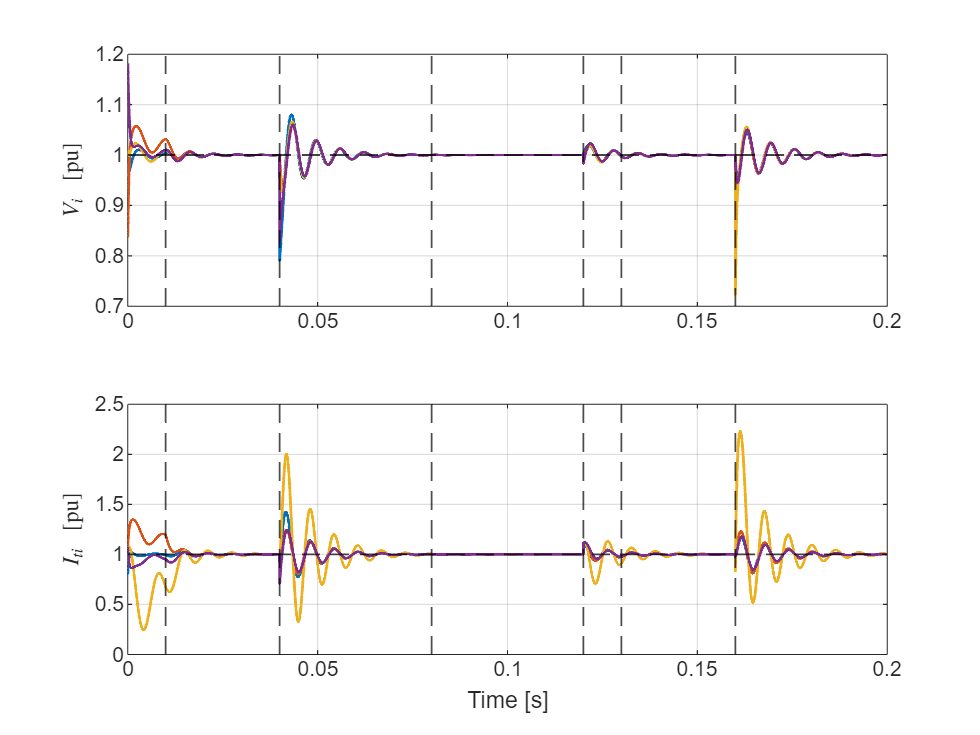

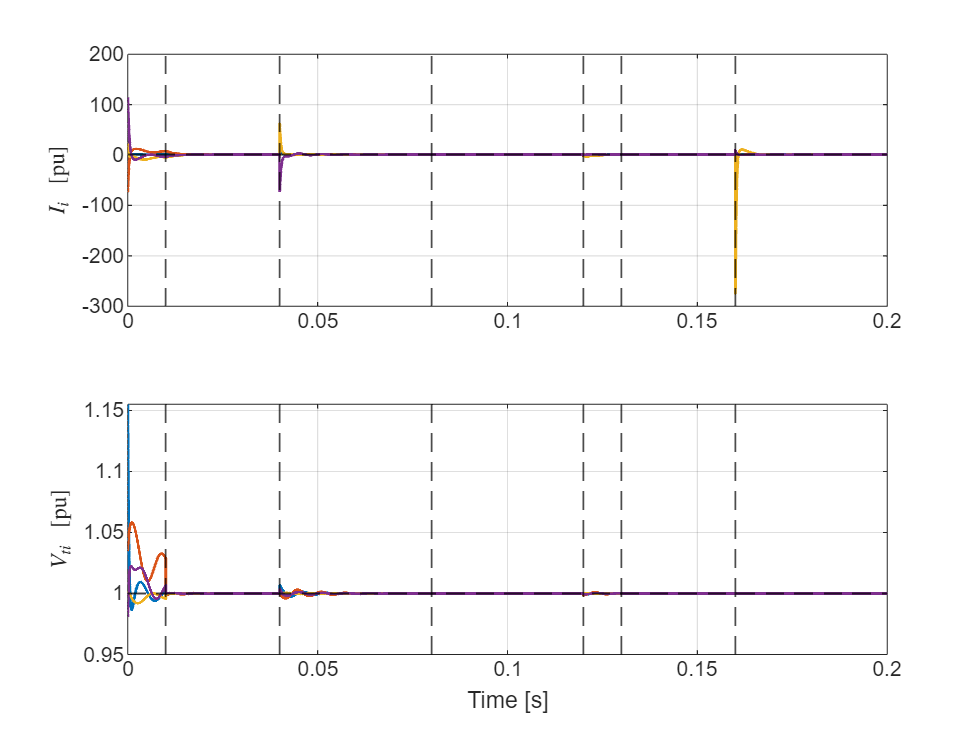

trajDataPU = drawStateTrajectories(t,X,U,Xs,Us,N,saveImages,figTitle);



% Draw topology 
% fig = figure('Color','w','Name',[figTitle,'-Topology']);
% figure(fig); clf; 
% ax = axes(fig); 
% net.draw(ax);
% 
% % Save Figure
% if saveImages
%     adjustAxesPadding(ax, 0, 0, 0, 0);
%     saveFigureHighRes([figTitle,'-Topology'], ...
%             'Width', 6, 'Height', 6, 'Units', 'inches', ...
%             'DPI', 600, 'FontSize', 6);
% end



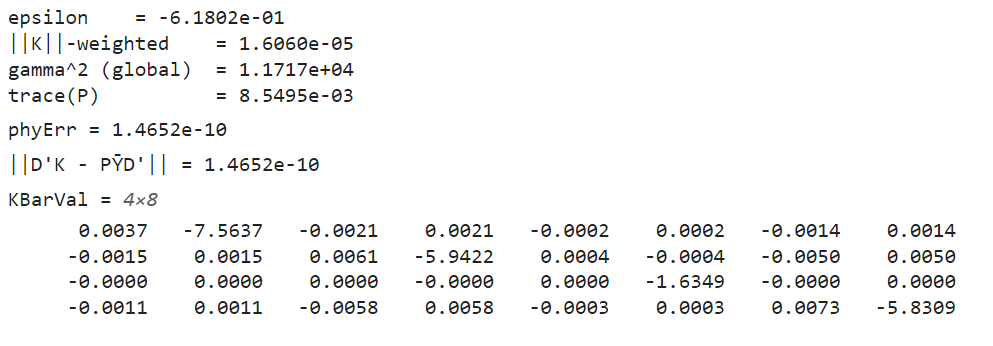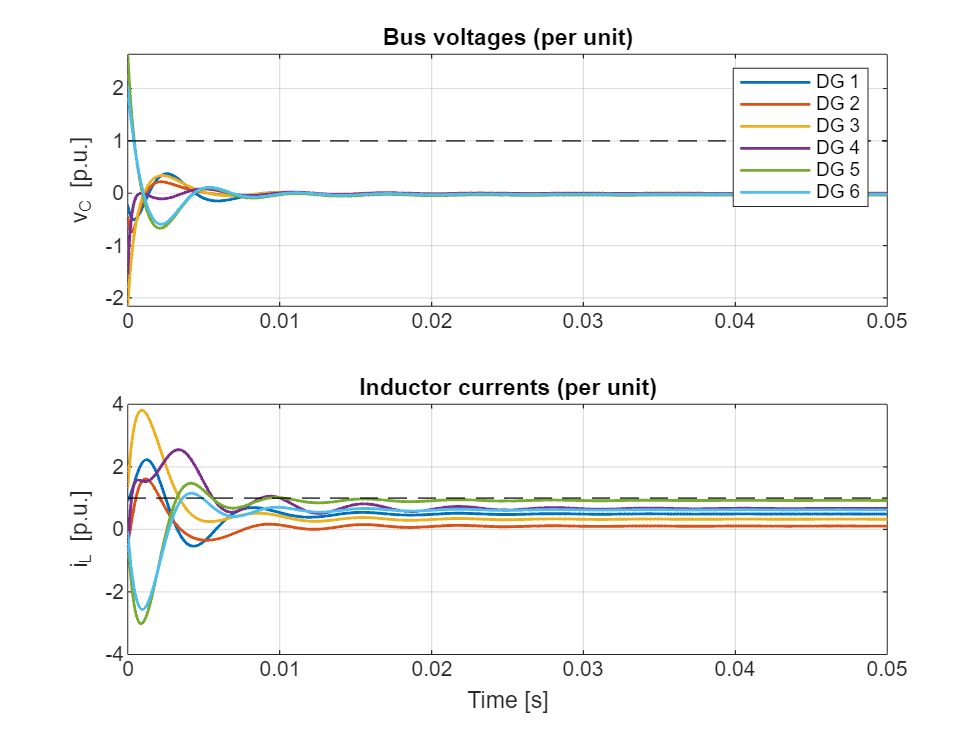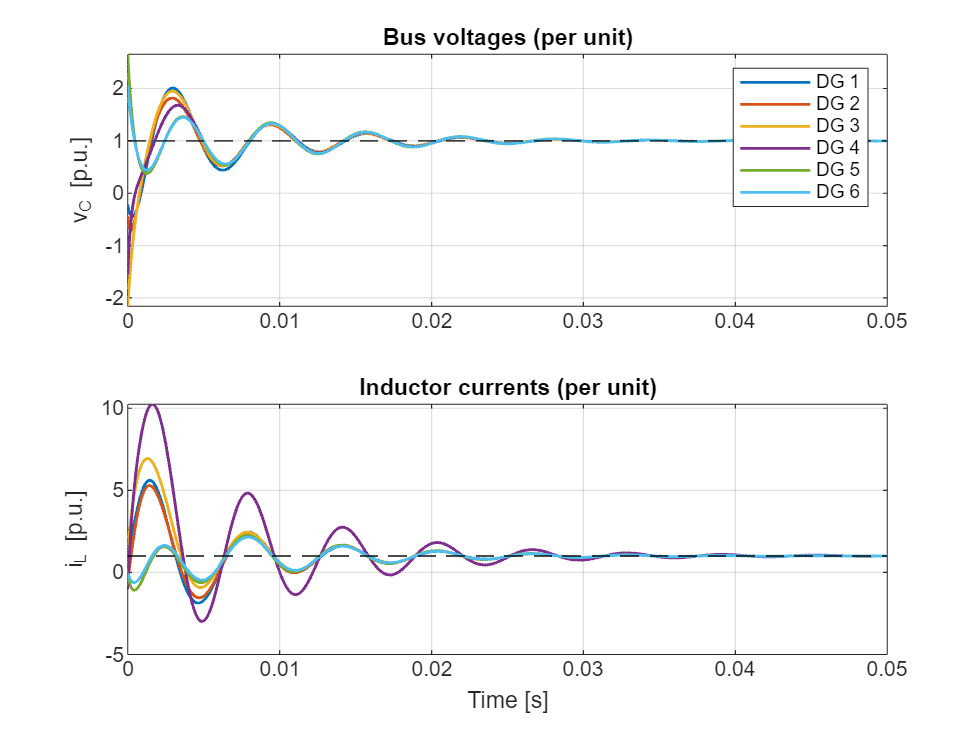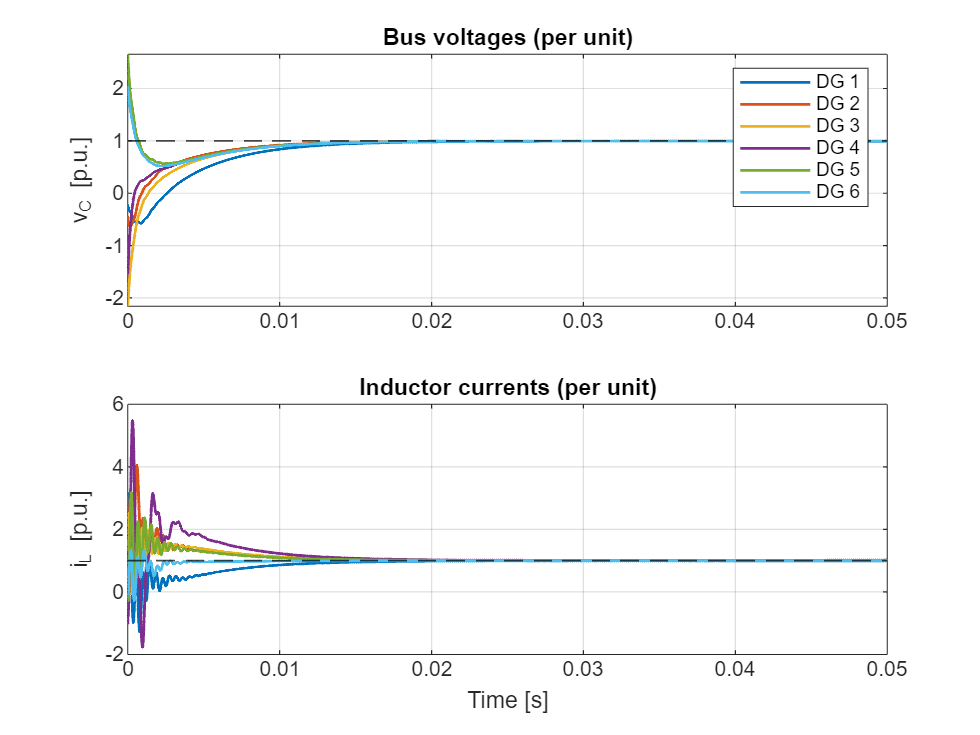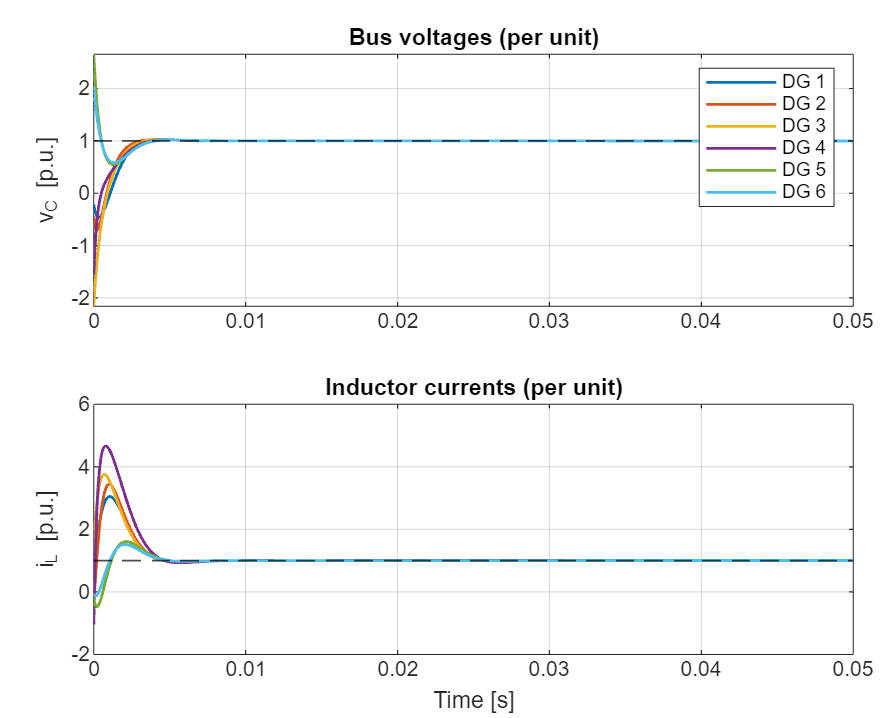

# Functions

## 1. Generating a random DC Microgrid

function net = getARandomDCMicrogrid(N)

    areaSide = 8;
    pos = areaSide*(rand(N,2)-0.5);            % random 2D positions
    
    % Reasonable DG parameter ranges
    Lvals = 1e-3 * (0.9 + 0.2*rand(N,1));      % 0.9–1.1 mH
    Cvals = 1e-3 * (0.9 + 0.2*rand(N,1));      % 0.9–1.1 mF
    Rfvals= 0.05 + 0.1*rand(N,1);              % 0.05–0.15 Ohm
    vref  = 48*ones(N,1);                      % 48 V nominal
    
    % --- DGs with per-node ratings ---
    %% ---------------- DGs with fixed Vr=48 and intentional ZI-load imbalance ----------------
    Vr_fixed = 48;                     % rated bus voltage for all DGs
    pctHeavy = 0.6;                   % fraction of "heavy" nodes (forces network flows)
    idxHeavy = randperm(N, ceil(pctHeavy*N));
    
    % Power rating bands (W) for light/heavy converters (affects Irated)
    Pr_light = [100 200];              % 2.5–5 A @ 48V
    Pr_heavy = [500 600];              % 5.4–8.8 A @ 48V
    
    % Impedance safety bounds (Ohm)
    DGs = repmat(DG(1,struct()), 1, N);
    for k = 1:N
        Vr_k = Vr_fixed;                % keep 48 V for every DG
    
        % Converter rating (Irated) via light/heavy bands
        if ismember(k, idxHeavy)
            Pr_k = randi(Pr_heavy);     % heavier converter capability
        else
            Pr_k = randi(Pr_light);
        end
        Ir_k = 2*Pr_k / Vr_k;             % A (converter rated current)
    
        % --- Z/I split for the **load** at this node (not converter rating) ---
        % Start with a Z share alphaZ ~ N(0.6,0.2), clamp, then compute P_Z, P_I.
        alphaZ = 0.6 + 0.2*randn();
        % Add per-node jitter to **load** power magnitude around converter rating to create mismatch
        Pload_k = Pr_k * (1.10 + 0.30*(2*rand()-1));   % ~Pr_k ±15%, biased +10% to induce imports
        PZ_k = alphaZ * Pload_k;              % Z-part power (W)
        PI_k = Pload_k - PZ_k;                 % I-part power (W)
    
        % Convert Z power to impedance and I power to constant current
        RL_k   = Vr_k^2 / PZ_k;   % Ohm
        Ibar_k = (PI_k / Vr_k) * (0.8 + 0.4*rand());  % A
    
        % --- Build DG object ---
        params = struct( ...
            'L',Lvals(k), 'C',Cvals(k), 'Rf',Rfvals(k), ...
            'RL', RL_k, 'Ibar', Ibar_k, ...           % ZI load parameters (→ plant)
            'Vrated', Vr_k, 'Irated', Ir_k, ...       % converter ratings
            'u_s', Vr_k, ...                         % start input near rated voltage
            'pos', pos(k,:), ...
            'x', [randn(1)*Vr_k; randn(1)*Ir_k], ...                       % initial state [vC;iL]
            'iload_fun', @(t) 0, ...                % no time ripple now (add later if needed)
            'K', [0 0] );
        DGs(k) = DG(k, params);
    end
    
    %% ----------- Proximity-based graph with min-length & length-proportional R -----------
    lines = {};
    idc   = 1;
    
    % --- Tunables ---
    minLen      = 1.0;                 % [arb units] minimum allowable line length
    proxRadius  = 3.0;                 % initial proximity radius (will grow if not connected)
    rho_per_len = 0.30;                % [Ohm / length-unit] base resistance per unit length
    randSpan    = 0.20;                % ±20% multiplicative randomness on R
    
    % Pairwise distances
    D = squareform(pdist(pos));        % NxN Euclidean distances
    
    % Helper to (re)build edge list for a given radius
    buildEdges = @(R) find(triu((D >= minLen) & (D <= R), 1));   % upper-triangular linear indices
    
    % Grow radius until connected (or until it’s obviously enough)
    maxTries = 10;
    for attempt = 1:maxTries
        Eidx  = buildEdges(proxRadius);
        [ii, jj] = ind2sub([N N], Eidx);
        Gtmp = graph(ii, jj, D(Eidx), N);
        if numedges(Gtmp) == 0
            proxRadius = proxRadius * 1.5;    % nothing yet; expand search
            continue;
        end
        comps = conncomp(Gtmp);
        if numel(unique(comps)) == 1
            break;                             % connected!
        else
            proxRadius = proxRadius * 1.35;    % not connected; expand and retry
        end
    end
    
    % If still not connected, force connectivity with an MST over *eligible* pairs
    if numel(unique(comps)) ~= 1
        % Allow all pairs >= minLen for MST
        W = D;
        W(D < minLen) = inf;                   % disallow too-short edges
        Gfull = graph(W);
        T = minspantree(Gfull,'Method','dense');
        ii = [ii; T.Edges.EndNodes(:,1)];
        jj = [jj; T.Edges.EndNodes(:,2)];
    end
    
    % Create TransmissionLine objects; R ∝ length with randomness
    for e = 1:numel(ii)
        i = ii(e); j = jj(e);
        len_ij = D(i,j);
        if isinf(len_ij) || len_ij < minLen, continue; end
        mult = 1 + randSpan*(2*rand()-1);      % in [1-randSpan, 1+randSpan]
        R_ij = rho_per_len * len_ij * mult;
        lines{end+1} = TransmissionLine(idc, i, j, R_ij); 
        idc = idc + 1;
    end
    
    Lines = [lines{:}];
    
    % Assemble microgrid
    net = DCMicrogrid(DGs, Lines);
    net.buildSystemMatrices();
    
    % ------ Steady state with epsilon matrices (equal current sharing) ------
    net.solveSteadyState();
    net.K = zeros(N, 2*N);
    
    x_s = net.x_s;
    mag = 0.2;
    x0 = x_s + x_s.*(mag*(2*rand(size(x_s))-1));
    net.setStateVector(x0);

end

## 2. Draw State Trajectories

function trajDataPU = drawStateTrajectories(t,X,U,Xs,Us,N,saveImages,figTitle)

    
    t_f = t(end);
    eventTimes = [];
    for eventTime = [0.05, 0.2, 0.4, 0.6, 0.65, 0.8]
        eventTimes = [eventTimes, eventTime*t_f];
    end
    
    It = zeros(numel(t), N);
    V = zeros(numel(t), N);
    I = zeros(numel(t), N);
    Vt = zeros(numel(t), N);

    Its = zeros(numel(t), N);
    Vs = zeros(numel(t), N);
    Is = zeros(numel(t), N);
    Vts = zeros(numel(t), N);
    
    for k = 1:N
        V(:,k) = X(:, 2*k-1);
        It(:,k) = X(:, 2*k);
        I(:,k) = U(:, 2*k-1);
        Vt(:,k) = U(:, 2*k);

        Vs(:,k) = Xs(:, 2*k-1);
        Its(:,k) = Xs(:, 2*k);
        Is(:,k) = Us(:, 2*k-1);
        Vts(:,k) = Us(:, 2*k);
    end

    % Per-Unit Values
    V_pu = V ./ Vs;
    It_pu = It ./ Its;
    I_pu = I ./ Is;
    Vt_pu = Vt ./ Vts;

    % Data storage
    trajDataPU.V_pu = V_pu;
    trajDataPU.It_pu = It_pu;
    trajDataPU.I_pu = I_pu;
    trajDataPU.Vt_pu = Vt_pu;

    % Plotting state and input trajectories
    figure('Name','Per-Unit States over time');
    subplot(2,1,1);
    plot(t, V_pu, 'LineWidth', 1.25);
    yline(1,'k--','LineWidth',0.8); grid on;
    ylabel('$V_i\ $ [pu]',Interpreter='latex'); 
    hold on
    for te = eventTimes
        xline(te, 'k--', 'LineWidth', 0.75);
    end

    subplot(2,1,2);
    plot(t, It_pu, 'LineWidth', 1.25);
    yline(1,'k--','LineWidth',0.8); grid on;
    ylabel('$I_{ti}\ $ [pu]',Interpreter='latex'); xlabel('Time [s]'); 
    % legend(arrayfun(@(k) sprintf('DG %d',k), 1:N, 'UniformOutput',false), Location="southoutside", Orientation="horizontal");
    hold on
    for te = eventTimes
        xline(te, 'k--', 'LineWidth', 0.75);
    end
    

    if saveImages
        saveFigureHighRes([figTitle,'-State'], ...
            'Width', 6, 'Height', 6, 'Units', 'inches', ...
            'DPI', 600, 'FontSize', 8);
    end
    
    figure('Name','Per-Unit Controls over time');
    subplot(2,1,1);
    plot(t, I_pu, 'LineWidth', 1.25);
    yline(1,'k--','LineWidth',0.8); grid on;
    ylabel('$I_i\ $ [pu]',Interpreter='latex'); 
    hold on
    for te = eventTimes
        xline(te, 'k--', 'LineWidth', 0.75);
    end
    

    subplot(2,1,2);
    plot(t, Vt_pu, 'LineWidth', 1.25);
    yline(1,'k--','LineWidth',0.8); grid on;
    ylabel('$V_{ti}\ $ [pu]',Interpreter='latex'); xlabel('Time [s]'); 
    % legend(arrayfun(@(k) sprintf('DG %d',k), 1:N, 'UniformOutput',false), Location="southoutside", Orientation="horizontal");
    hold on
    for te = eventTimes
        xline(te, 'k--', 'LineWidth', 0.75);
    end
    

    if saveImages
        saveFigureHighRes([figTitle,'-Input'], ...
            'Width', 6, 'Height', 6, 'Units', 'inches', ...
            'DPI', 600, 'FontSize', 8);
    end
end

## 3. Saving Figures

function saveFigureHighRes(baseName, varargin)
%SAVEFIGUREHIGHRES Save a figure as high-res PNG and FIG, with padding.
%
%   saveFigureHighRes('myPlot')
%   saveFigureHighRes('myPlot','Width',6,'Height',4,'FontSize',14,'DPI',300)
%   saveFigureHighRes('myPlot','Padding',20)   % padding in points

    % ---- Defaults ----
    defaults.Figure   = gcf;
    defaults.Width    = 6;           % in Units
    defaults.Height   = 4;           % in Units
    defaults.Units    = 'inches';    % 'inches','centimeters',...
    defaults.DPI      = 300;
    defaults.FontSize = 14;
    defaults.Padding  = 20;          % points around content

    % ---- Parse inputs ----
    p = inputParser;
    addRequired(p,'baseName',@(x)ischar(x) || isstring(x));
    addParameter(p,'Figure',   defaults.Figure);
    addParameter(p,'Width',    defaults.Width,  @isnumeric);
    addParameter(p,'Height',   defaults.Height, @isnumeric);
    addParameter(p,'Units',    defaults.Units,  @ischar);
    addParameter(p,'DPI',      defaults.DPI,    @isnumeric);
    addParameter(p,'FontSize', defaults.FontSize,@isnumeric);
    addParameter(p,'Padding',  defaults.Padding,@isnumeric);

    parse(p,baseName,varargin{:});
    R = p.Results;

    fig = R.Figure;

    % ---- Set figure size on screen ----
    set(fig,'Units',R.Units);
    pos = get(fig,'Position');
    pos(3) = R.Width;
    pos(4) = R.Height;
    set(fig,'Position',pos);

    % % ---- Font size for all text/axes ----
    % if ~isempty(R.FontSize)
    %     objs = findall(fig,'-property','FontSize');
    %     set(objs,'FontSize',R.FontSize);
    % end

    % ---- File names ----
    baseName = char(baseName);
    pngName  = ['Results/', baseName '.png'];
    figName  = ['Results/', baseName '.fig'];

    % ---- Save high-res PNG (with padding so labels aren’t cut) ----
    % Works in R2020a+; for older versions we can fall back to print.
    try
        exportgraphics(fig, pngName, ...
            'Resolution',     R.DPI, ...
            'ContentType',    'image', ...
            'BackgroundColor','white', ...
            'Padding',        R.Padding);
    catch
        % Fallback for older MATLAB
        set(fig,'PaperUnits',R.Units, ...
                'PaperPosition',[0 0 R.Width R.Height], ...
                'PaperPositionMode','manual');
        print(fig, pngName, '-dpng', sprintf('-r%d',R.DPI));
    end

    % ---- Save FIG ----
    savefig(fig, figName);

    fprintf('Saved figure as: %s and %s\n', pngName, figName);
end

## 4. Cropping Figures

function adjustAxesPadding(ax, padLeft, padRight, padBottom, padTop)
%adjustAxesPadding Expand axes limits with independent padding for each side.
%
%   adjustAxesPadding(ax, padLeft, padRight, padBottom, padTop)
%
%   Each padding value is a *fraction* of the total data range.
%   Examples:
%       adjustAxesPadding(gca, 0.05, 0.05, 0.05, 0.05);   % symmetric 5%
%       adjustAxesPadding(gca, 0.10, 0.02, 0.08, 0.15);   % per-side padding

    if nargin < 5
        error('Need 5 arguments: ax, padLeft, padRight, padBottom, padTop.');
    end

    ch = ax.Children;

    % Initialize bounds
    xmin = inf; xmax = -inf;
    ymin = inf; ymax = -inf;

    for k = 1:numel(ch)
        obj = ch(k);

        % LINE, SCATTER, etc (XData / YData)
        if isprop(obj, 'XData') && isprop(obj, 'YData')
            x = obj.XData(:);
            y = obj.YData(:);
            xmin = min(xmin, min(x));
            xmax = max(xmax, max(x));
            ymin = min(ymin, min(y));
            ymax = max(ymax, max(y));
        end

        % TEXT objects (use extent box)
        if isa(obj, 'matlab.graphics.primitive.Text')
            ext = obj.Extent; % [x, y, width, height]
            xmin = min(xmin, ext(1));
            xmax = max(xmax, ext(1) + ext(3));
            ymin = min(ymin, ext(2));
            ymax = max(ymax, ext(2) + ext(4));
        end

        % PATCH (Vertices)
        if isprop(obj, 'Vertices')
            verts = obj.Vertices;
            if ~isempty(verts)
                xmin = min(xmin, min(verts(:,1)));
                xmax = max(xmax, max(verts(:,1)));
                ymin = min(ymin, min(verts(:,2)));
                ymax = max(ymax, max(verts(:,2)));
            end
        end
    end

    % Compute ranges
    dx = xmax - xmin;
    dy = ymax - ymin;

    % Apply per-side padding
    newXmin = xmin - padLeft;
    newXmax = xmax + padRight;
    newYmin = ymin - padBottom;
    newYmax = ymax + padTop;

    % Apply limits
    ax.XLim = [newXmin newXmax];
    ax.YLim = [newYmin newYmax];
end
